clear all; clc; close all; warning off; format shortG; % % housekeeping

**The model**:

# Please update the model equations in "model_system.m" file in the same/current directory.

% open('model_system.m')

#### Information on representative parameter values, initial conditions, time span and labels

# Please input y0, tspan, and prm_WT

filename = 'GT_val.mat';
prm_name = {'\delta', 'b', '\beta', 'k12', 'k23', 'k31'};

var_label = {'V1', 'V2', 'V3'};
y0        = [5,      0,   0]; % initial conditions
tspan     = [0, 72]; % maximum length of experiment


 Now we have to specify/choose the parameters at which the sensitivity analysis is to be done. These are saved as column vectors of "prm"

**Creating "prm" based on a nominal guess**

delta = 0.1; base_prd = 0.05; beta = 1; k12 = 2; k23 = 3; k31 = 4;
prm_WT = log10([delta; base_prd; beta; k12; k23; k31]);
% NOTE: VALUES ARE PROVIDED IN LOG SCALE

**Alternate 1**: Nominal values of the model parameters

**Alternate 2**: When we want to consider an uncertainty - Suppose there is a three-fold (passed through **log_fac**) uncertainty on either side in the value of the third and fourth parameters (passed through **par_id_vec**). And we take four samples (passed through **num_g**) in this range. Sampling via Latin HyperCube Sampling

alternate_prm = 1;
if alternate_prm == 1
    prm(:, 1) = prm_WT;
elseif alternate_prm == 2
    log_fac = log10(3);     par_id_vec = [3; 4];     num_g = 4;
    
    R_mat = lhsdesign(num_g, size(par_id_vec, 1), 'iterations', 5); % sampling "[0, 1]^size(par_id_vec, 1)" using LHS
    PERT_mat = (2 * R_mat - 1) * log_fac; % scaling the randomness to three-fold on either sides
    for guess_ind = 1:num_g
        prm(:, guess_ind) = prm_WT;
        for par_id_ind = 1:size(par_id_vec, 1)
            prm(par_id_vec(par_id_ind, 1), guess_ind) = PERT_mat(guess_ind, par_id_ind) + prm_WT(par_id_vec(par_id_ind, 1), 1);
        end
    end
end

Now we can have another/additional set of parameter combinations at which the evaluation is to be done. These are saved as column vectors of "prm_test". Note evaluation is done on parameter combinations listed in prm.

#### Creating "prm_test":

**A nominal guess**

delta = 0.1; base_prd = 0.05; beta = 1; k12 = 2*1.5; k23 = 3; k31 = 4;
prm_test_WT = log10([delta; base_prd; beta; k12; k23; k31]);


**Alternate 1**: Nominal values of the model parameters

**Alternate 2**: When we want to consider an uncertainty - Suppose there is a three-fold (passed through log_fac) uncertainty on either side in the value of the third and fourth parameters (passed through par_id_vec). And we take four samples (passed through num_g) in this range. Sampling via Latin HyperCube Sampling

**Alternate 3**: A mean of the first two parameter samples of prm

alternate_prm_test = 0;
if alternate_prm_test == 1
    prm_test(:, 1) = prm_test_WT;
elseif alternate_prm_test == 2
    log_fac = log10(3);     par_id_vec = [3; 4];     num_g_test = 2;
    
    R_mat_test = lhsdesign(num_g_test, size(par_id_vec, 1), 'iterations', 5); % sampling "[0, 1]^size(par_id_vec, 1)" using LHS
    PERT_mat_test = (2 * R_mat_test - 1) * log_fac; % scaling the randomness to three-fold on either sides
    for guess_ind = 1:num_g_test
        prm_test(:, guess_ind) = prm_test_WT;
        for par_id_ind = 1:size(par_id_vec, 1)
            prm_test(par_id_vec(par_id_ind, 1), guess_ind) = PERT_mat_test(guess_ind, par_id_ind) + prm_test_WT(par_id_vec(par_id_ind, 1), 1);
        end
    end
elseif alternate_prm_test == 3
    prm_test(:, 1) = (prm(:, 1) + prm(:, 2))/2;
else
    % no prm_test
end

clear prm_WT delta base_prd beta k12 k23 k31 log_fac par_id_vec num_g R_mat PERT_mat;
clear par_id_vec num_g_test R_mat_test PERT_mat_test;
save(filename)

Plotting the dynamics: Set see_plots = 1 if you want to see the dynamics predicted for the parameter combinations listed in prm.

see_plots = 0;
if see_plots == 1
    if (~exist('prm') || ~exist('tspan') || ~exist('y0'))
        load('GT_val.mat', 'prm', 'tspan', 'y0')
    end
    for prm_sample = 1:size(prm, 2)
        figure; hold on; clear t y;
        disp(['Visualizing the dynamics plots for parameter sample, s#', num2str(prm_sample)]);
        [t, y] = ode45(@(t, y) model_system(t, y, prm(:, prm_sample)), tspan, y0);
        for ind = 1:size(y, 2)
            plot(t, y(:, ind)); legend_text{1, ind} = ['V ', num2str(ind)];
        end
        xlabel('Time'); ylabel('Molecules'); legend(legend_text); legend boxoff; hold off;
    end
end
% close all;

### PARSEC Part 1: Performing Sensitivity analysis

A **blind sensitivity analysis** to choose the variables to use. We specify specs_tim_d for the analysis. The analysis is stored in the directory called "**Results**".

# Please input specs_tim_d

% feasible measurement time points are at every 2 units
specs_tim_d = 3;

% see_TSA_plots = 1: to see the sensitivity analysis plots
see_TSA_plots = 0;

if ~exist('prm') || ~exist('y0')
    load('GT_val.mat', 'prm', 'y0')
end


addpath 'TSA'; % Sensitivity analysis functions are in this directory
for prm_sample = 1:size(prm, 2)
    clear TSA_file Z; % comment if using parfor
    [Z, TSA_file] = Model_efast(specs_tim_d, [1:size(y0, 2)]', prm_sample);
end

Results/TSA_prm1_3unit.mat


Parameter values provided in log scale and uses ode45/or ode23s solver

Parameter values will be fluctuating between fac_lower*nominal_value and fac_upper*nominal_value where fac_lower = 1.2^(-1); fac_upper = 1.2. This can be changed in lines 57 and 58 of Model_efast

if see_TSA_plots == 1
    disp('Visualizing the TSA plots for individual variables (unlabelled, x_axis = time, y_axis = Si(parameter, variable))');
    for prm_sample = 1:size(prm, 2)
        disp(['Sensitivity profiles @ Sample #', num2str(prm_sample)])
        plot_TSA_indi(specs_tim_d, prm_sample);
    end
end


#### Selecting measurement specs based on constraints and above plots:

Suppose V1 can't be measured. V2 and V3 seem to be lighting up for most parameters.

# Please input specs_var_interest

specs_var_interest = [2; 3]; % variables 2 and 3 are considered in the design.

% see_TSA_plots = 1: to see the sensitivity analysis plots
see_TSA_plots = 0;


Sensitivity analysis based on the variables of interest (this will overwrite the earlier matlab files for TSA results) The analysis is stored in the directory called "Results".

addpath 'TSA'; % Sensitivity analysis functions are in this directory
if ~exist('prm')
    load('GT_val.mat', 'prm')
end
if ~exist('specs_tim_d')
    specs_tim_d = 3;
end

addpath 'TSA'; % Sensitivity analysis functions are in this directory
full_Z = [];
parfor prm_sample = 1:size(prm, 2)
    % clear TSA_file Z; % comment if using parfor
    [Z, TSA_file] = Model_efast(specs_tim_d, specs_var_interest, prm_sample);
    TSA_file_names{1, prm_sample} = TSA_file;
    full_Z = [full_Z, Z(:, 1:size(Z, 2) - 1)];
    Z_3d(:, :, prm_sample) = Z(:, 1:size(Z, 2) - 1);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
Results/TSA_prm1_3unit.mat


disp(TSA_file_names);

    {'Results/TSA_prm1_3unit.mat'}



save(['TSA_full_', num2str(specs_tim_d), 'unit.mat'], 'TSA_file_names', 'full_Z', 'Z_3d');


Visualizing the TSA plots (unlabelled, x_axis = time, y_axis = Si(parameter, variable))

if see_TSA_plots == 1
    disp('Visualizing the TSA plots (unlabelled, x_axis = time, y_axis = Si(parameter, variable))');
    for prm_sample = 1:size(prm, 2)
        disp(['Sensitivity profiles @ Sample #', num2str(prm_sample)])
        plot_TSA_indi(specs_tim_d, prm_sample);
    end
end

### PARSEC Part 2: Clustering and making designs

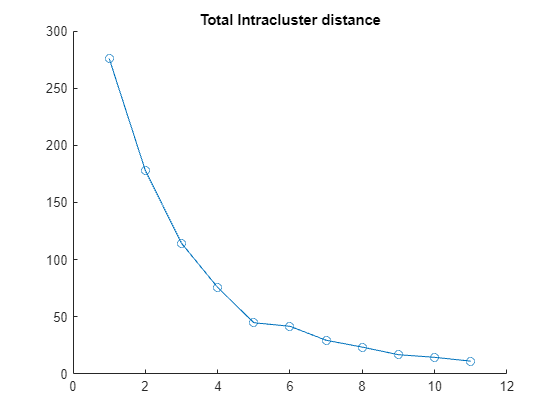

% % some PARSEC options
n_expt = 10; % number of realization of design. PARSEC is a stochastic algorithm

if ~exist('specs_tim_d') || ~exist('specs_var_interest')
    specs_tim_d = 3; specs_var_interest = [2; 3];
end

load(['TSA_full_', num2str(specs_tim_d), 'unit.mat'], 'full_Z');

max_sample_size = max(floor(size(full_Z, 1) - 2)/2, 2);
% max_sample_size = 25; % uncomment if user-defined max_sample_size is preferred.

n_cluster_vec = [1:1:max_sample_size]'; % vector of experiment sample size of interest


addpath 'PARSEC'; % Clustering and data generation functions are in this directory

for n_cluster_ind = 1:size(n_cluster_vec, 1)
    n_cluster = n_cluster_vec(n_cluster_ind, 1);
    [D_file, intra_d_mean, intra_d_stdev] = make_designs(n_cluster, n_expt, full_Z, specs_tim_d, specs_var_interest);
    intra_d_mean_vec(n_cluster_ind, :) = [n_cluster, intra_d_mean];
end

% % add axes labels
figure; hold on;
double_derivatives = diff(diff(intra_d_mean_vec(:, 2)));
[~, optiK] = max(double_derivatives); optiK = optiK + 2;
plot(intra_d_mean_vec(:, 1), intra_d_mean_vec(:, 2), '-o');
% plot(intra_d_mean_vec(optiK, 1), intra_d_mean_vec(optiK, 2), 'r*', 'Markersize', 20);
title('Total Intracluster distance')

% disp(['Guess for optimal sample size: ', num2str(optiK)])
selected_samplesize = max(optiK + [-2:1:1]', 0) + 1; % selected range of sample size or unique choice based on above results


**Select the number of clusters**

# Please modify the selected_samplesize

go_with_suggested = 0;

if go_with_suggested == 1
    % selected_samplesize is as above
else
    % choose your own sample size vector (can be singleton) of interest

    selected_samplesize = 6; % selected range of sample size or unique choice based on above results
    % selected_samplesize = [3:1:10]'; % selected range of sample size or unique choice based on above results
end

disp(['Designing experiments for the following sample sizes: ', mat2str(selected_samplesize')])

Designing experiments for the following sample sizes: [3 4 5 6 7 8 9 10]




show_designs = 0; % fraction of designs to show at random. Input 0 to supress the plot
if ~exist('specs_tim_d') || ~exist('specs_var_interest')
    specs_tim_d = 3; specs_var_interest = [2; 3];
end
addpath 'PARSEC'; % Clustering and data generation functions are in this directory

for n_cluster_ind = 1:size(selected_samplesize, 1)
    D_file = ['Results/DES_', num2str(specs_tim_d), 'unit/D',  num2str(selected_samplesize(n_cluster_ind, 1))];
    
    gen_data(selected_samplesize(n_cluster_ind, 1), specs_tim_d, D_file, show_designs)
    % PARAMETER VALUES PROVIDED IN LOG SCALE AND USES ODE45 SOLVER
end

### Evaluating the designs

cd design_evaluation;
% open('macro_fitting.m'); % execute this for the evaluation
% open('fit_setup_file_UD.m');
% open('error_function.m');

**macro_fitting**: code for high-throughput analysis of the designs generated. The fitting options are input through **fit_setup_file_UD**. The chi_sq function which is minimized using macro_fitting is mentioned in **error_function**.

macro_fitting generates the results of the fitting in a folder created in the parent directory where the live script is present. In the folder, prefixed with 'RES' is a sub-folder named 'C<num_cluster>' containing three types of result files:

(a) diary file: information about fitting options and initial conditions, execution time and so on.

(b) fit result (full): the entire session of parameter estimation for the design is stored. Updated every iteration in the estimation.

(c) fit result (short 'sh'): a concise version of the full result file containing the selected parameter combinations, and so on.

Please toggle the following in **fit_setup_file_UD**:

- info.diary_reqd = 1: to display and print the diary file

- info.work_progress_nest = 0: to display which iteration of parameter estimation is currently being executed.

- info.work_progress_time = 0: to display the progress of the current iteration of parameter estimation.

if ~exist('specs_tim_d') || ~exist('selected_samplesize') || ~exist('n_expt')
    specs_tim_d = 3; selected_samplesize = [3:1:7]'; n_expt = 10;
end
macro_fitting(specs_tim_d, selected_samplesize, n_expt)

Results saved in ../RES_3unit/C3/full_train PARSEC_ED1_s1.mat


% PARAMETER VALUES PROVIDED IN LOG SCALE AND USES ODE45 SOLVER
cd ..;

**evaluation_of_prm_estm**: the result of parameter estimation from macro_fitting is analyzed to evaluate how accurate the parameter estimation was using the different designs. This is summarized in the eval_file (MATLAB data file and excel book) in the 'C<num_cluster>' folder

In the excel workbook:

Sheet 1: (column-wise) list of the experiment design labels, the ground-truth value of parameter combination used for the generation of data, the time-points associated with the design, the total sample size and the estimation error corresponding to the design.

Sheet 2: (column-wise) list of the experiment design labels and statistics of the estimation error corresponding to the design. Since ABC-FAR (parameter estimation algorithm used here) selects a number of parameter combinations at the end, the statistics is based on that. Thirs column onwards, the first quartile, median and the third quartile, along with the mean are reported.

Sheet 3: (column-wise) list of the experiment design labels and the mean of the estimation error corresponding to the design.

Sheet 4: (column-wise) ranking of the designs based on their estimation error, list of the experiment design labels and the estimation error corresponding to the design. This is followed by a fraction indicating the number of PARSEC designs with estimation error less than or equal to the value in the third column. This is followed by a fraction indicating the number of RANDOM designs with estimation error less than or equal to the value in the third column.

Sheets 1-4 correspond to training designs. Training designs are those where the data set is generated at parameter values used for sensitivity analysis.

Sheets 5 and 6 are equivalet to sheets 3 and 4 respectively, but are for test designs. They are generated when test analysis is done. Test designs are those where the data set is generated at parameter values nit used for sensitivity analysis.

**display_summary**: displays the top designs based on parameter estimation error metric (**show_rows** = number of designs to show), and plots a comparison of PARSEC and RANDOM designs (if **plot_cd** = 1). The comparison is based on ranking (if **plot_cd_rank** = 1) or estimation error otherwise.

cd design_evaluation;

if ~exist('specs_tim_d') || ~exist('selected_samplesize') || ~exist('n_expt')
    specs_tim_d = 3; selected_samplesize = 6; n_expt = 10;
end
show_rows = 3; plot_cd = 0; plot_cd_rank = 0;

for ind = 1:size(selected_samplesize, 1)
    disp('____________________________________________________________________')
    n_cluster = selected_samplesize(ind, 1);
    ar = evaluation_of_prm_estm(n_cluster, specs_tim_d, n_expt);
    acc_ratio(ind, 1) = ar; clear ar;
    display_summary(n_cluster, specs_tim_d, show_rows, plot_cd, plot_cd_rank)
    disp(' ')
end

____________________________________________________________________


evaluation_of_prm_estm is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\RR\Downloads\hcharsh PARSEC_ABC-FAR main PARSEC_codes\PARSEC_eg1_Represilator\design_evaluation

Change the MATLAB current folder or add its folder to the MATLAB path.

cd ..;

f1 = figure; ax1 = axes('Parent', f1); hold on;
plot(selected_samplesize, acc_ratio, '-k', 'Linewidth', 1.5);
xlabel('Sample size'); ylabel('Accuracy ratio');
set(ax1, 'FontSize', 12, 'Linewidth', 1);